# CAPÍTULO 10 - LÁMINAS DE REVOLUCIÓN

Calcula tensiones meridionales y circunferenciales mediante equilibrio de membrana para cilindros, casquetes esféricos o conos con presión axisimétrica.

Dimensión: superficie 3D de revolución con hipótesis axisimétrica. Las curvas meridionales son 2D porque la solución no depende del ángulo de giro.

Modifica los datos y pulsa Run. Las funciones de cálculo están en esta misma carpeta. Abre INICIAR_CURSO.m y ejecútalo una vez al iniciar MATLAB.

## 1. Datos / Input data

Unidades de entrada: m, N, Pa, rad y s, salvo que se indique otra unidad. Los valores iniciales son editables y no seleccionan un ejercicio concreto.

assert(exist('rm_lineal','file')==2, 'Ejecuta INICIAR_CURSO.m una vez antes de abrir los capitulos.');

tipo puede ser "cilindro", "esfera" o "cono". z crece hacia abajo. fuerzaAxialExtra se suma a la fuerza del cierre inicial; un valor positivo aumenta la tracción meridional. En la esfera se excluye el polo para evitar la singularidad de las coordenadas.

tipo="cilindro";
radio=.5; longitud=1; anguloCono=25*pi/180;
espesor=.004;
presionInicial=1e6; densidadLiquido=0; gravedad=9.81;
fuerzaAxialExtra=0;
E=210e9; nu=.3; limiteElastico=250e6;
numeroPuntos=301;

## 2. Geometría y presión

assert(radio>0 && longitud>0 && espesor>0 && numeroPuntos>=20,'Geometria invalida.');
if tipo=="cilindro"
    z=linspace(0,longitud,numeroPuntos)'; r=radio+zeros(size(z));
    coseno=ones(size(z)); km=zeros(size(z)); kt=1./r;
elseif tipo=="esfera"
    phi=linspace(.025,pi/2,numeroPuntos)';
    z=radio*(1-cos(phi)); r=radio*sin(phi); coseno=sin(phi);
    km=ones(size(z))/radio; kt=km;
else
    assert(tipo=="cono" && anguloCono>0 && anguloCono<pi/2,'Tipo de lamina invalido.');
    z=linspace(0,longitud,numeroPuntos)'; r=radio+z*tan(anguloCono);
    coseno=cos(anguloCono)+zeros(size(z)); km=zeros(size(z)); kt=coseno./r;
end
p=presionInicial+densidadLiquido*gravedad*(z-z(1));
assert(all(p>=0) && limiteElastico>0,'Presion o limite invalido.');

## 3. Equilibrio meridional y ecuación de Laplace


$$N_m=\frac{F_z}{2\pi r\cos\alpha},\qquad N_m\kappa_m+N_\theta\kappa_\theta=p,\qquad \sigma_m=N_m/t,\quad\sigma_\theta=N_\theta/t$$


Fz es la fuerza axial acumulada sobre la parte recortada. Se integra la componente axial de la presión y se añade el cierre inicial. Las curvaturas km y kt son los inversos de los radios principales. El espesor divide las fuerzas por longitud para obtener tensiones.

fuerzaInicial=p(1)*pi*r(1)^2+fuerzaAxialExtra;
Fz=fuerzaInicial+cumtrapz(r,2*pi*p.*r);
Nm=Fz./(2*pi*r.*coseno);
Nt=(p-km.*Nm)./kt;
sigmaM=Nm/espesor; sigmaT=Nt/espesor;
equivalente=sqrt(sigmaM.^2+sigmaT.^2-sigmaM.*sigmaT);
factor=limiteElastico/max(max(equivalente),realmin);
errorLaplace=max(abs(km.*Nm+kt.*Nt-p));
resultado=struct('sigmaM',sigmaM,'sigmaT',sigmaT,'factor',factor,'errorLaplace',errorLaplace);
disp("Factor de seguridad von Mises: "+factor);

Factor de seguridad von Mises: 2.3094


disp("Mayor razon espesor/radio de curvatura: "+max(espesor*max(abs(km),abs(kt))));

Mayor razon espesor/radio de curvatura: 0.008


disp("Residuo de Laplace [Pa]: "+errorLaplace);

Residuo de Laplace [Pa]: 0


## 4. Tensiones de membrana

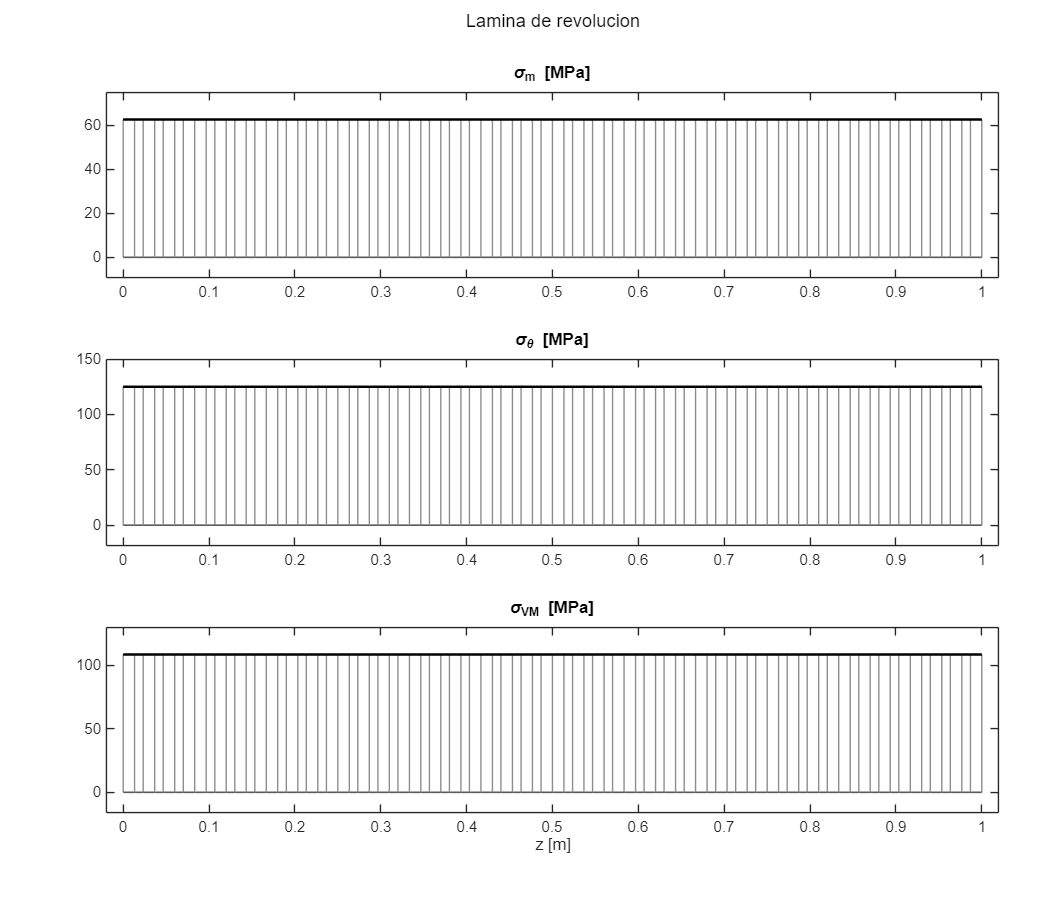

[figura,ejes]=rm_figura(3,'Lamina de revolucion');
rm_curva(ejes(1),z,sigmaM/1e6,'\sigma_m [MPa]');
rm_curva(ejes(2),z,sigmaT/1e6,'\sigma_\theta [MPa]');
rm_curva(ejes(3),z,equivalente/1e6,'\sigma_{VM} [MPa]'); xlabel(ejes(3),'z [m]');

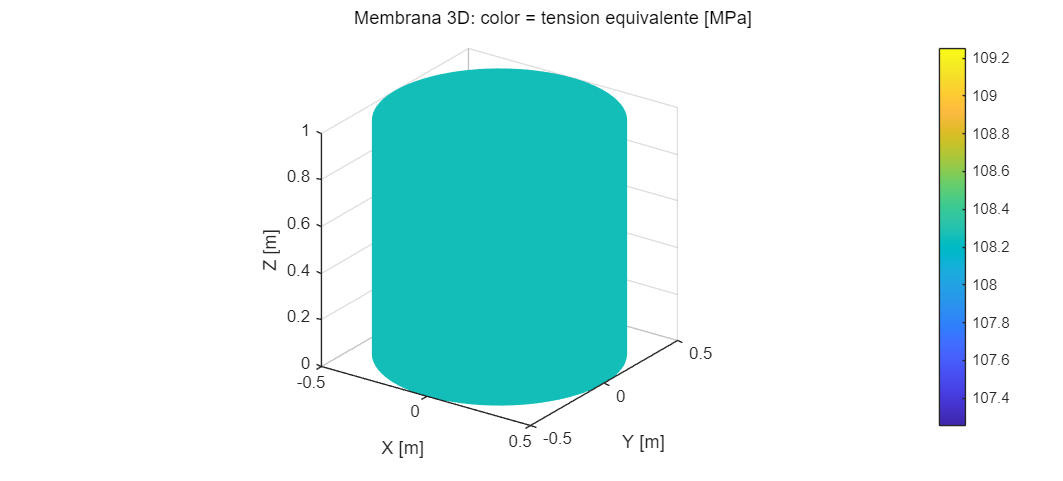

azimut=linspace(0,2*pi,81);
X=r*cos(azimut);Y=r*sin(azimut);Z=z*ones(size(azimut));
[figura,ejes]=rm_figura(1,'Membrana 3D: color = tension equivalente [MPa]');
surf(ejes(1),X,Y,Z,(equivalente/1e6)*ones(size(azimut)),'EdgeColor','none');
axis(ejes(1),'equal');view(ejes(1),35,24);colorbar(ejes(1));
xlabel(ejes(1),'X [m]');ylabel(ejes(1),'Y [m]');zlabel(ejes(1),'Z [m]');

## Funciones utilizadas

cumtrapz: acumula una integral por trapecios. Aquí suma la componente axial de presión sobre el perfil.

sin, cos y tan: evalúan relaciones trigonométricas en radianes. Aquí describen el perfil y la orientación de la membrana.

sqrt: calcula la raíz cuadrada. Aquí forma la tensión equivalente de un estado plano.

disp muestra valores; aquí presenta las tablas y conclusiones. assert comprueba una condición; aquí rechaza datos incompatibles. table reúne columnas con nombre; aquí permite leer resultados con unidades. rm_figura prepara ejes verticales; aquí reserva espacio para títulos y unidades. rm_curva dibuja una magnitud; aquí diferencia el cero gris de la curva negra y el rayado.

GUIA_MATLAB.md, en esta misma carpeta, explica las operaciones básicas en general y con un ejemplo de su uso en estos capítulos.

## Alcance y conexiones

Láminas delgadas, convexas, axisimétricas y sin momentos de borde. Admite presión uniforme o hidrostática y fuerza axial en el corte inicial. No predice flexión local de uniones, singularidades de ápices ni pandeo por presión externa.

Conexión con lo anterior: La verificación equivalente utiliza el capítulo 8; la compatibilidad tridimensional completa de una cáscara no se resuelve aquí.

Cambiar datos no requiere editar las ecuaciones. Una geometría, ley de material o condición fuera del alcance indicado requiere ampliar el modelo. Un cálculo que satisface equilibrio no demuestra por sí solo resistencia o estabilidad suficiente.

disp('Capitulo 10: calculo completado.');

Capitulo 10: calculo completado.
